# **HW 2 computer assignment **

### **Part 1: Create Nearest Neighbor Classifier **

**Reshaping training and testing images **

Thare are 5000 training images and 500 testing images each with 28x28 pixels. If the training and testing images are visualized as stacked blocks, we can transform the training images into 784x5000 and testing images into 784x500 matrices. 

If we proceed to transpose the training and testing matrices into 5000x784 and 500x784 matrices, this way each row of the training and testing matrices contain the information of each image.

reshaped_imageTrain = reshape(imageTrain,[28*28,5000])

reshaped_imageTrain =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0   

reshaped_imageTrain = transpose(reshaped_imageTrain) % training matrix is now 5000x784

reshaped_imageTrain =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0   

reshaped_imageTest = reshape(imageTest,[28*28,500])

reshaped_imageTest =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0    

reshaped_imageTest = transpose (reshaped_imageTest) % testing matrix is now 500x784

reshaped_imageTest =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0    

**Initializing parameters **

K = 3;  % let's consider the 3 nearest neighbors 
size_of_test = size (reshaped_imageTest, 1); 
size_of_train = size (reshaped_imageTrain, 1); 

predictions = zeros(size_of_test, 1); 

euclidean_list = zeros(size_of_test, size_of_train); 
    % matrix will be updated to contain sorted euclidean distances

euclidean_index = zeros(size_of_test, size_of_train); 
    % matrix will be updated to contain the index of sorted euclidean distances

**Calculate Euclidean distances** 

- Due to the reshaping, every row now contains information of an image. 

- The 2 for loops below will calculate the Euclidean distances by taking every row of testing image matrix and subtract the row of every training images; the values of each subtraction are then summed and square rooted. 

- The Euclean values will then be sorted from smallest to largest and stored in 'euclidian_list'. The location of their indexes will be stored in 'euclidian_list'

for test_index=1:size_of_test % take every point of testing data for 500 data points

    for train_index=1:size_of_train %every point of training data for 5000 data points
       distance = (reshaped_imageTest(test_index,:)-reshaped_imageTrain(train_index,:)).^2; 
       euclidean_list(test_index,train_index)=sqrt(sum(distance)); 
    end

       [euclidean_list(test_index,:),euclidean_index(test_index,:)] = sort( ...
           euclidean_list(test_index,:)); 

end 

**Finding the K nearest neighbors** 

knn=euclidean_index(:,1:K); % takes the first 3 smallest or shortest Euclidean distances
 
for i=1:size(knn,1)

    most_common=mode(labelTrain(knn(i,:)')); 
        % the function 'mode' gives the most occuring value in an array

    predictions(i)=most_common; % the predicted number is stored

end

**Calculating the error of each class from 0 to 9 by calling function 'calc_error'**

A function name 'calc_error' is used to calculate the error of each class to avoid redundancy. Due to how Matlab is structured the function can only be placed at the bottom of the script. 

Below is what the function looks like, the real location of the function is at the very bottom. 

% function[error] = calc_error(labelTest, predictions, target_number)
%  
%     a = find(labelTest==target_number); 
%     error = length(find(labelTest(a)~=predictions(a)))/length(labelTest(a))*100;

%     %error plot for each class
%     figure 
%     plot (labelTest(a), 'o'); 
%     hold on 
%     plot (predictions(a),'x'); 
%     legend ('True Labels', 'Predictions within this class'); 
%     ylabel('Class'); 
%     xlabel('Number of data');  
%     ylim ([0 10]); 

% end

%To be put into funtion calc_error
true_labels = labelTest; 
predicted_labels= predictions;

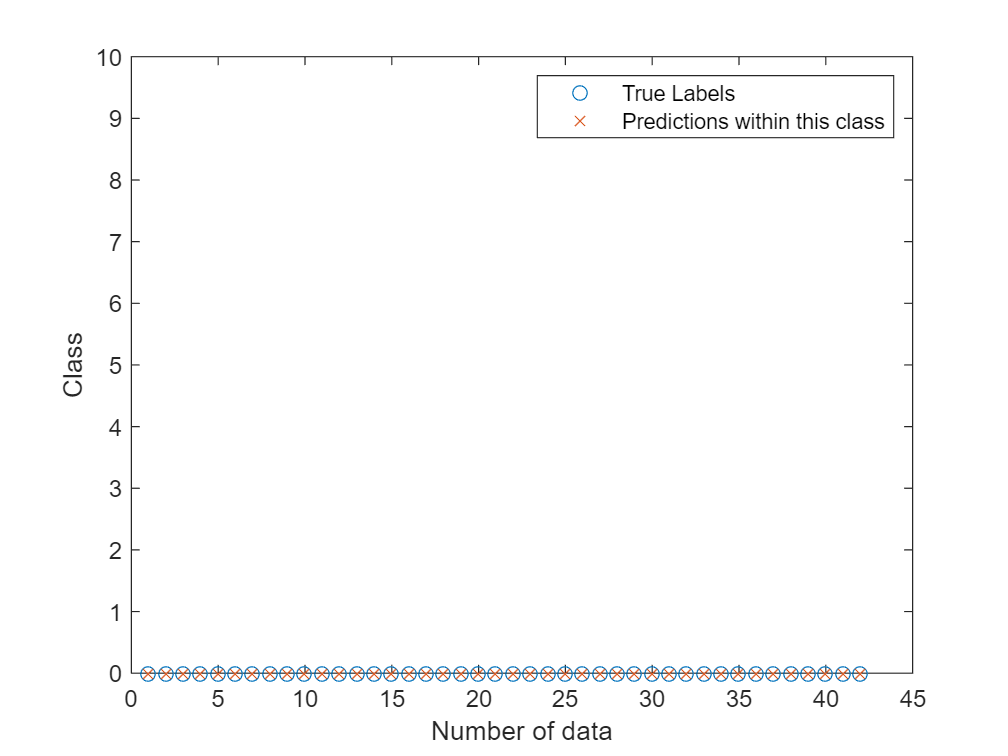

error_class_0 = calc_error(true_labels, predicted_labels,0); 

error_class_0

error_class_0 = 0

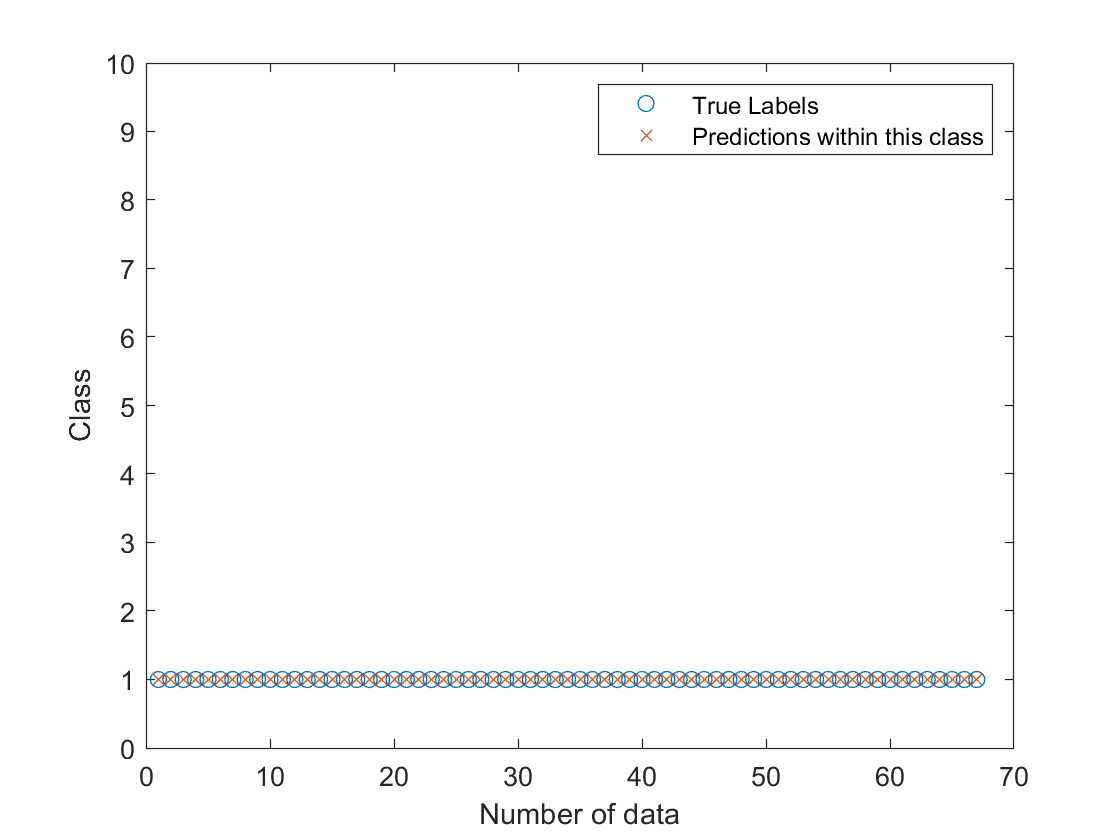

error_class_1 = calc_error(true_labels, predicted_labels,1); 

error_class_1

error_class_1 = 0

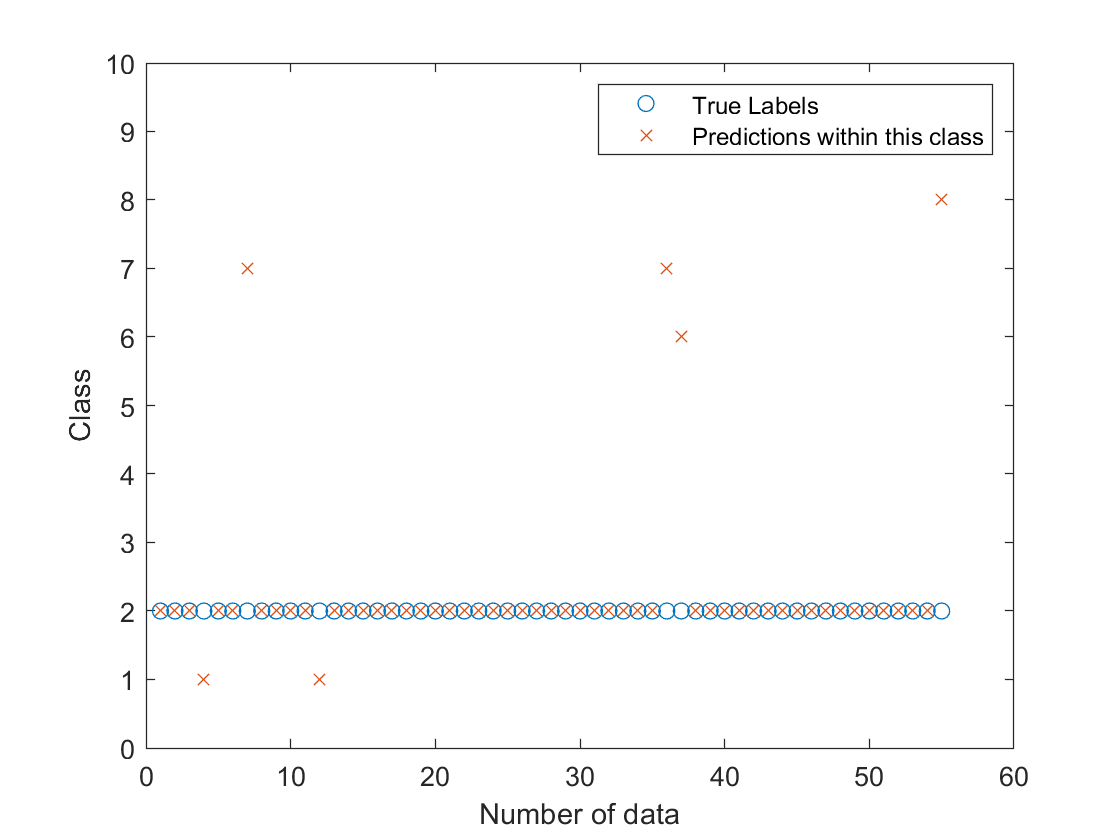

error_class_2 = calc_error(true_labels, predicted_labels,2); 

error_class_2

error_class_2 = 10.9091

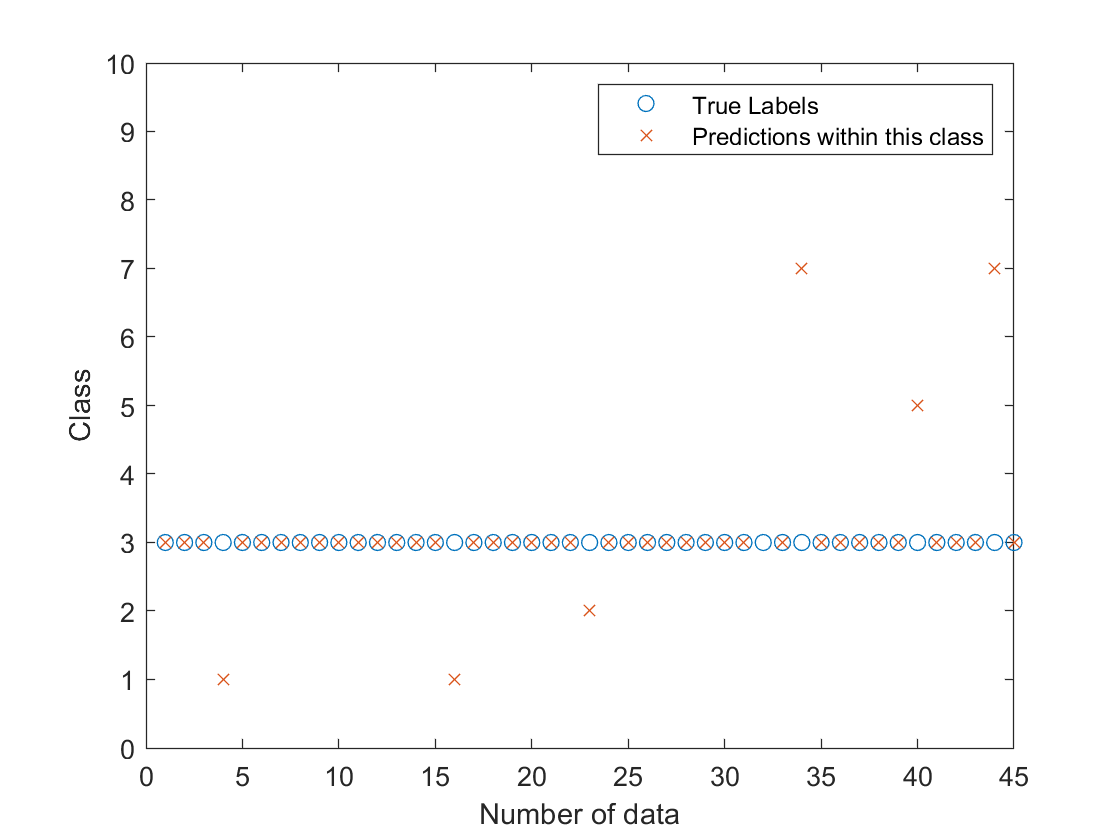

error_class_3 = calc_error(true_labels, predicted_labels,3); 

error_class_3

error_class_3 = 15.5556

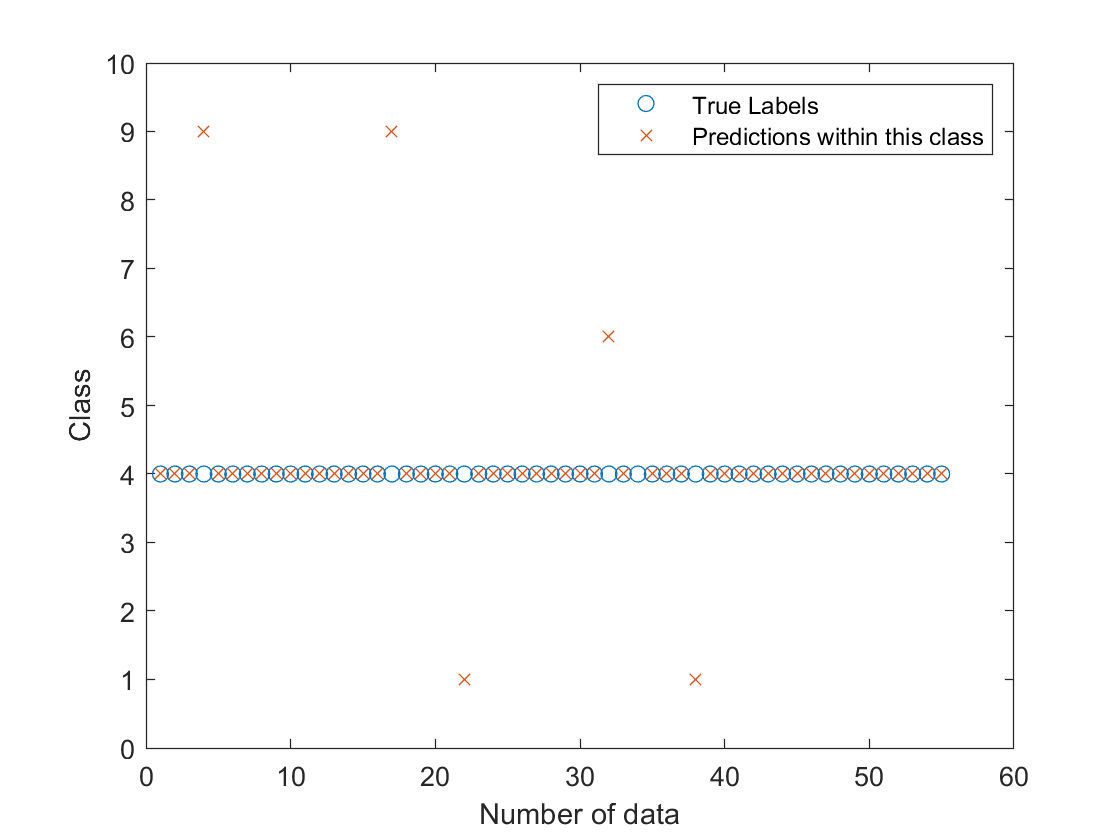

error_class_4 = calc_error(true_labels, predicted_labels,4); 

error_class_4

error_class_4 = 10.9091

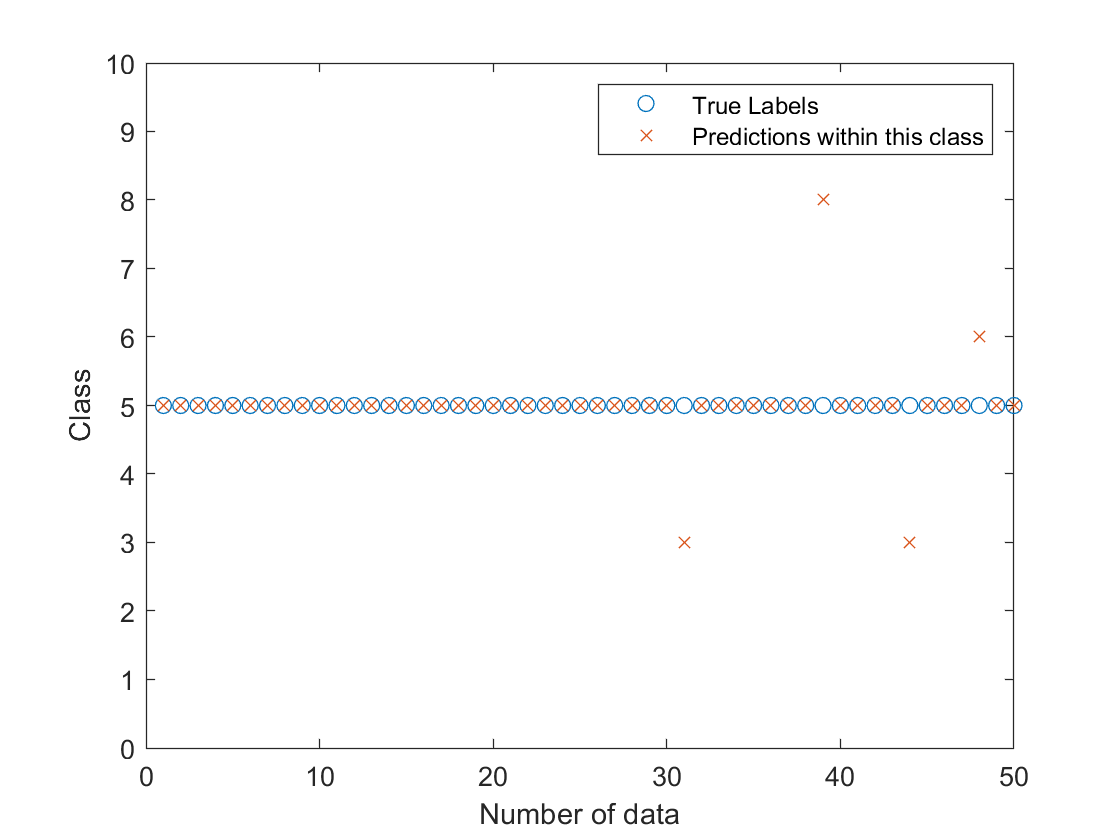

error_class_5 = calc_error(true_labels, predicted_labels,5); 

error_class_5

error_class_5 = 8

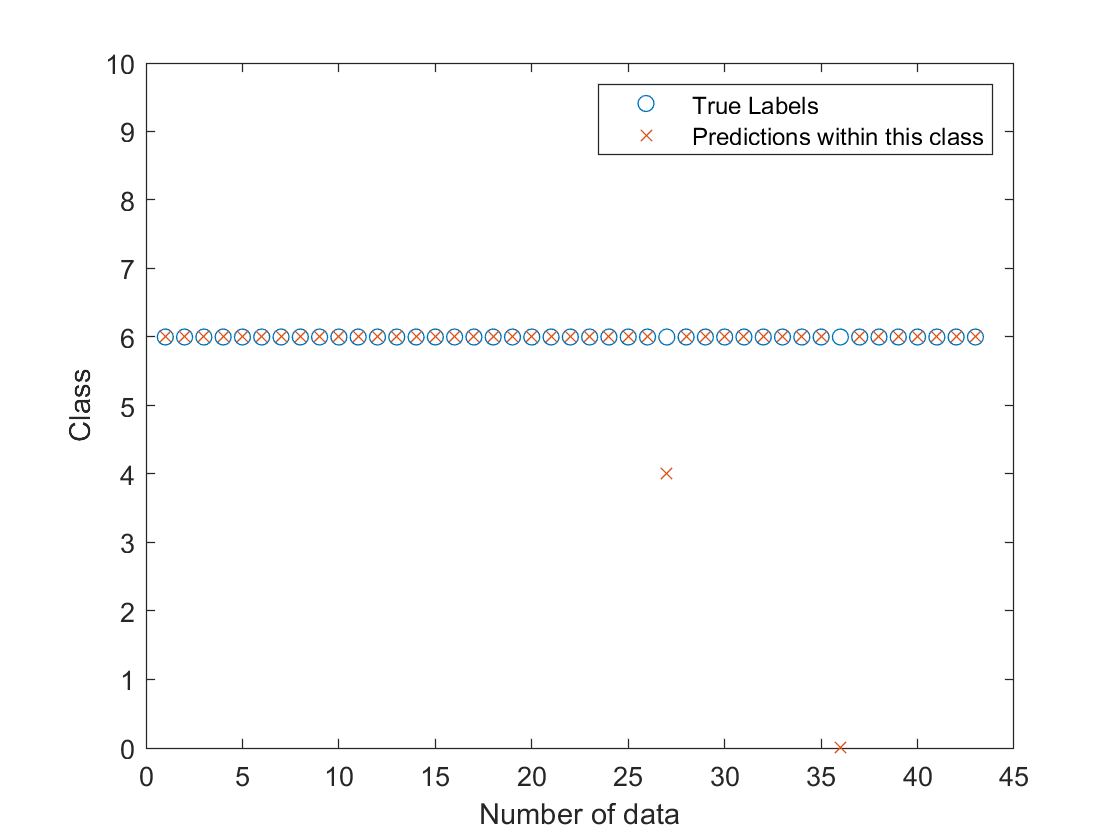

error_class_6 = calc_error(true_labels, predicted_labels,6); 

error_class_6

error_class_6 = 4.6512

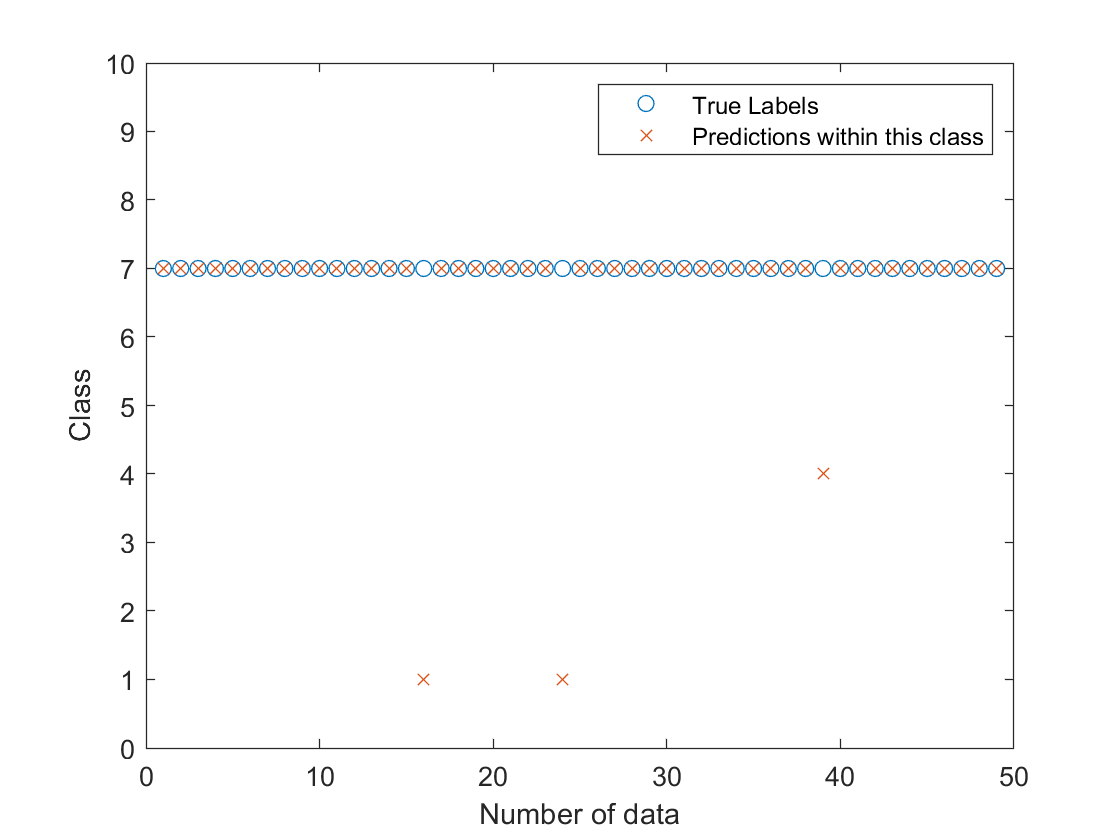

error_class_7 = calc_error(true_labels, predicted_labels,7); 

error_class_7

error_class_7 = 6.1224

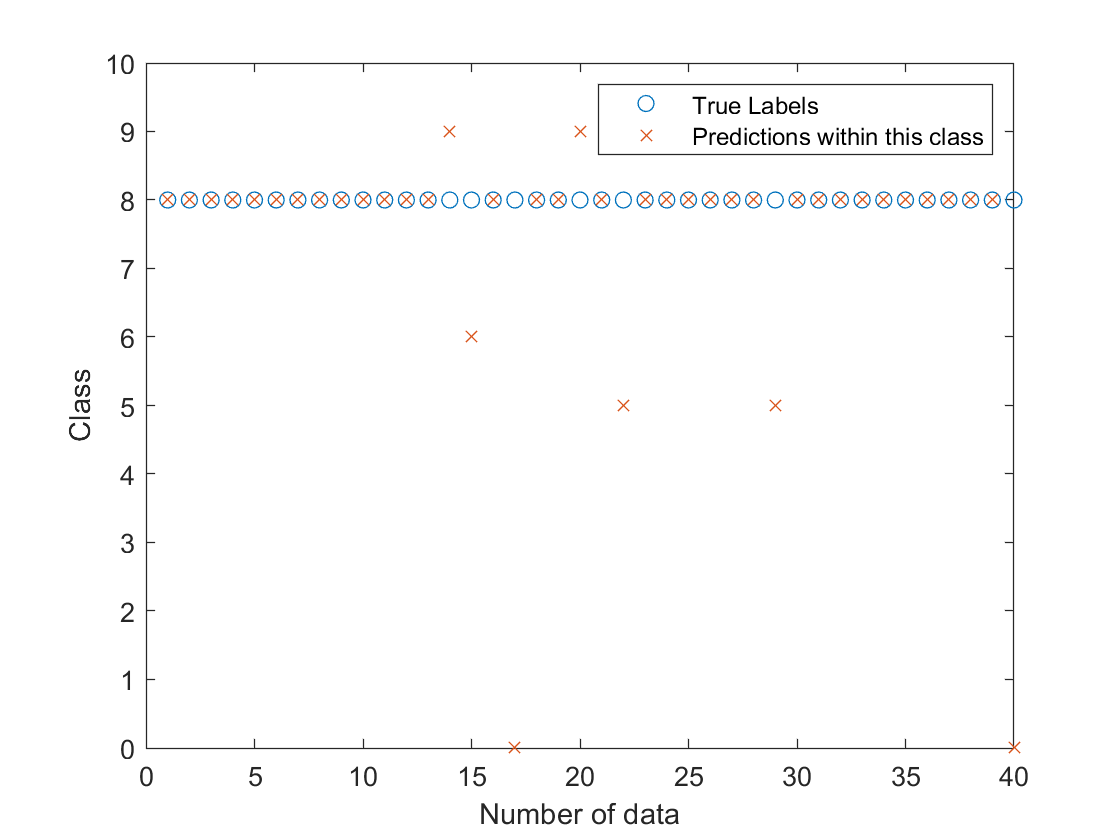

error_class_8 = calc_error(true_labels, predicted_labels,8); 

error_class_8

error_class_8 = 17.5000

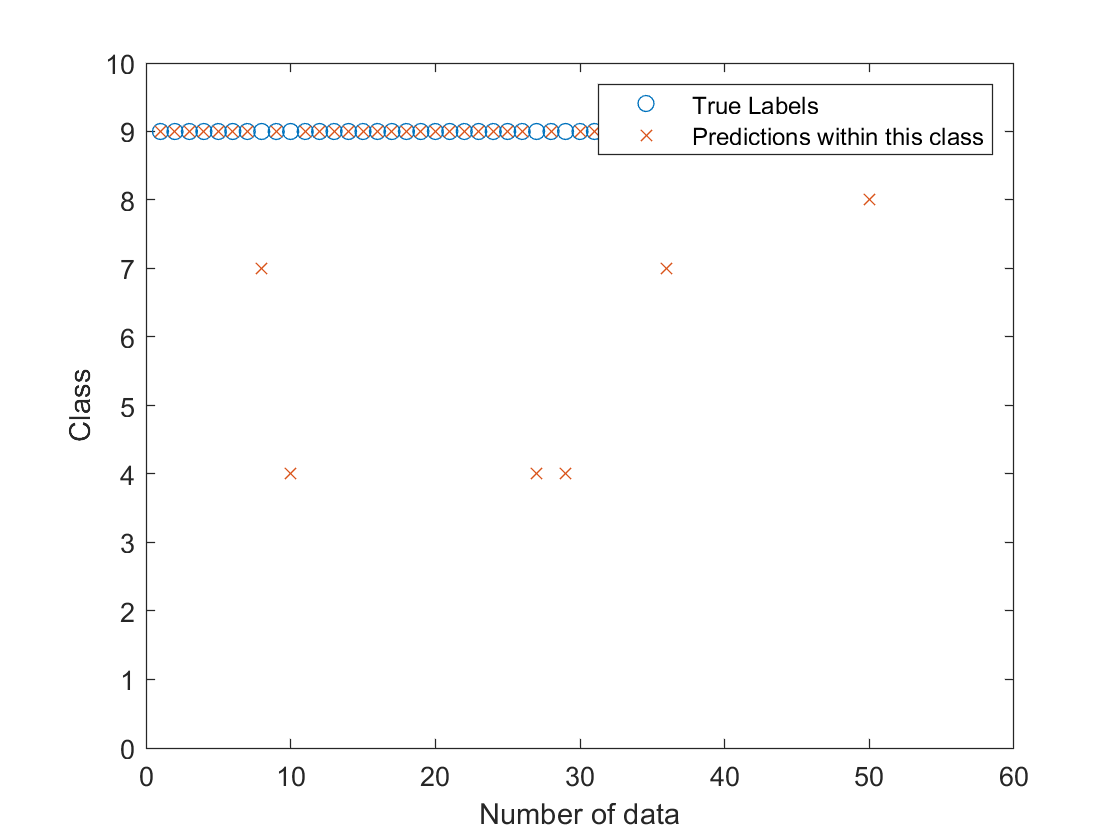

error_class_9 = calc_error(true_labels, predicted_labels,9); 

error_class_9

error_class_9 = 11.1111

### Part 2: Calculating accuarcy rate and error rate

**Below is the total accuracy rate of the classifier **

total_accuracy = size (find(predictions==labelTest),1)/size(labelTest,1)*100; 
disp(total_accuracy); 

   91.8000



**Below is the total error rate of the classifier**

total_error = size (find(predictions~=labelTest),1)/size(labelTest,1)*100; 
disp(total_error); 

    8.2000



**Confusion matrix to visualize data **

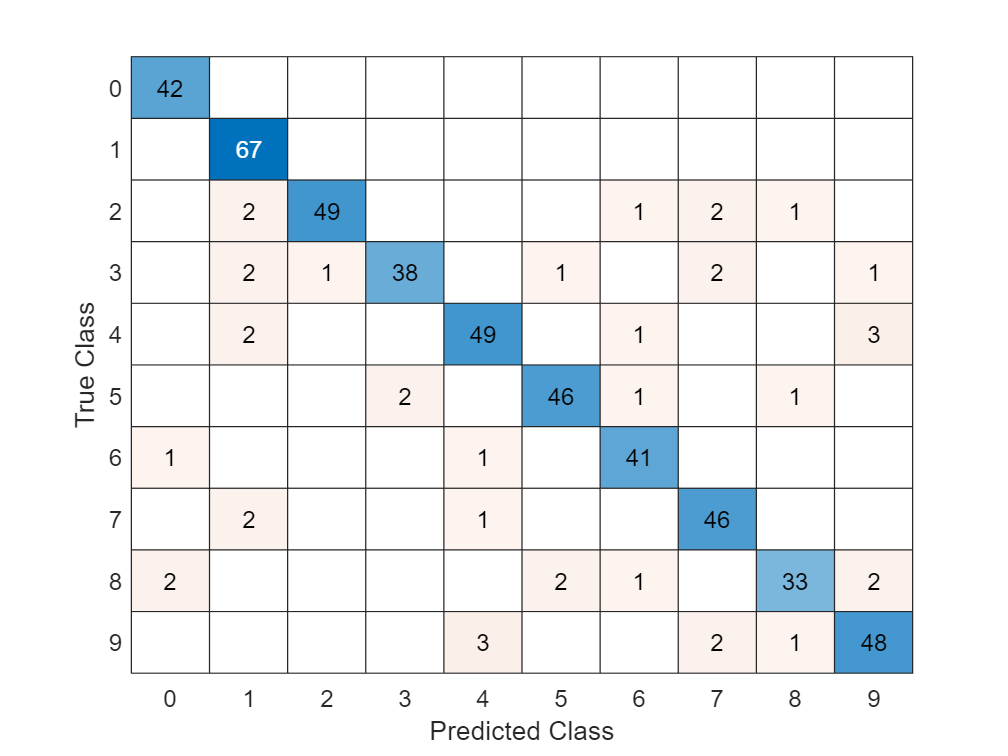

figure 
Confusion_matrix = confusionchart(labelTest,predictions);

### Part 3: Explaining misclassified images 

**According to the error rates there are 41 images that are mis-classified. We will look at the first 5 cases. **

index_mis_classified = find(predictions~=labelTest);
disp((index_mis_classified)'); % we will observe images at index 25, 44, 45, 74, 78

  Columns 1 through 27

    25    44    45    74    78    93   112   116   150   160   176   196   242   243   246   248   251   258   265   267   291   301   320   321   322   327   339

  Columns 28 through 41

   342   350   359   368   382   404   413   446   450   465   479   480   493   496



**Image 1 **

fprintf('Below is the true image 1')

Below is the true image 1

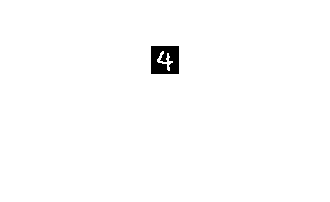

image1 = imshow(imageTest(:,:,index_mis_classified(1))); 

image1_comp_index = mode(euclidean_index(index_mis_classified(1),1:K)); 
                    % gives index of the misclassified image
fprintf('Below is what image 1 was misclassified as')

Below is what image 1 was misclassified as

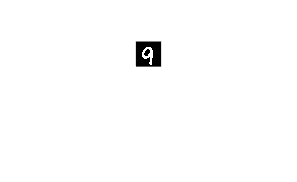

comp1 = imshow(imageTrain(:,:,image1_comp_index)); 

fprintf('At index 25, 4 was misclassified as 9'); 

At index 25, 4 was misclassified as 9

nearest_neigh_1 = labelTrain(knn(index_mis_classified(1),:)'); 
disp(nearest_neigh_1); 

     9
     9
     4



Explanation 1:

The classifier could have failed to identify 4 and 9 due to their similar features, which implies near equal Euclidean distances. At first look number 4 and number 9 are very similar to each other. Their features both include legs, and curved shape on the left side to complete the number. The main difference between the numbers are probably the gap at the top of number 4. During classification, the 3 nearest neighbors include two 9s and one 4, which mean the classifier was almost correct but probably made a mistake due to their distances being equal to one another. 

**Image 2**

fprintf('Below is the true image 2')

Below is the true image 2

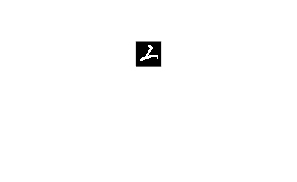

image2 = imshow(imageTest(:,:,index_mis_classified(2))); 

image2_comp_index = mode(euclidean_index(index_mis_classified(2),1:K)); 
fprintf('Below is what image 2 was misclassified as')

Below is what image 2 was misclassified as

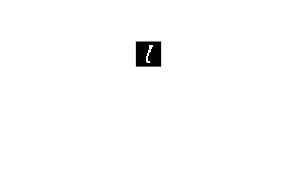

comp2 = imshow(imageTrain(:,:,image2_comp_index)); 

fprintf('At index 44, 2 was misclassified as 1'); 

At index 44, 2 was misclassified as 1

nearest_neigh_2 = labelTrain(knn(index_mis_classified(2),:)'); 
disp(nearest_neigh_2); 

     1
     1
     1



Explanation 2: 

The classifier could have misidentified this image due to the tiny curve at the end of number 1 which makes it look like number 2. The nearest neighbors of this image are all 1, which implies that the Euclidean distances of number 1 in training are probably closed enough to number 2. Furthermore, looking at the confusion matrix it seems like number 2 is often misclassified and has one of the highest error rate. This is likely due to number 2 sharing many features with other number; such as the long straight line of number 1, round top of number 6, or the swan-like curve of number 7. 

**Image 3**

fprintf('Below is the true image 3')

Below is the true image 3

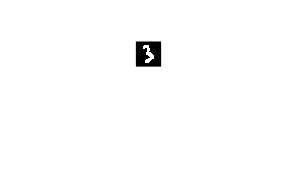

image3 = imshow(imageTest(:,:,index_mis_classified(3))); 

image3_comp_index = mode(euclidean_index(index_mis_classified(3),1:K)); 
fprintf('Below is what image 3 was misclassified as')

Below is what image 3 was misclassified as

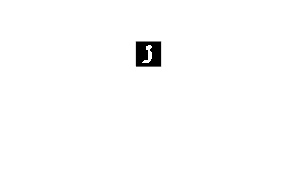

comp3 = imshow(imageTrain(:,:,image3_comp_index)); 

fprintf('At index 45, 3 was misclassified as 1'); 

At index 45, 3 was misclassified as 1

nearest_neigh_3 = labelTrain(knn(index_mis_classified(3),:)'); 
disp(nearest_neigh_3); 

     5
     3
     1



Explanation 3: 

This is an interesting case because the number 3 has three different nearest neighbors (3,5,1) and at the end the classifier choose number 1 to represent the number at this index. This shows that there is a limit to the 'mode' function that was employed in the classifier. This is also a problem with choosing the appropriate K value to reflect the number of nearest number because K=3 might be best for some classes but worse for other classes. Furthermore, if we look the image 3 was misclassified as this number is misshapen and ambiguous since it seems  to share the features of all number 3,5, and 1. This similarity in features would be one of the reasons why the classifier failed to identify this image. 

**Image 4**

fprintf('Below is the true image 4')

Below is the true image 4

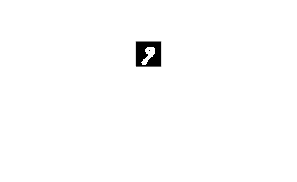

image4 = imshow(imageTest(:,:,index_mis_classified(4))); 

image4_comp_index = mode(euclidean_index(index_mis_classified(4),1:K)); 
fprintf('Below is what image 4 was misclassified as')

Below is what image 4 was misclassified as

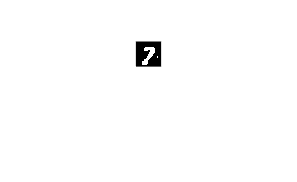

comp4 = imshow(imageTrain(:,:,image4_comp_index)); 

fprintf('At index 74, 9 was misclassified as 7'); 

At index 74, 9 was misclassified as 7

nearest_neigh_4 = labelTrain(knn(index_mis_classified(4),:)'); 
disp(nearest_neigh_4); 

     7
     9
     7



Explanations 4: 

At first glance, number 9 and 7 in this case both share the 'slanted-body' feature which makes them look extremely similar to each other. This feature probably make their Euclidean distances almost equal to each other, resulting number 7 to be the most common nearest neighbor eventhough the number 9 was considered as one of the neighbors too. Similar features or misshapen numbers are often the main culprits for why the classifier fail to identify a number. 

**Image 5**

fprintf('Below is the true image 5')

Below is the true image 5

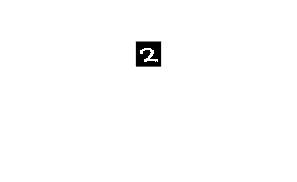

image5 = imshow(imageTest(:,:,index_mis_classified(5))); 

image5_comp_index = mode(euclidean_index(index_mis_classified(5),1:K)); 
fprintf('Below is what image 5 was misclassified as')

Below is what image 5 was misclassified as

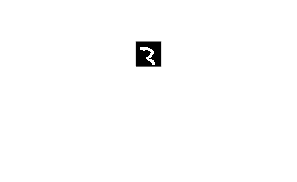

comp5 = imshow(imageTrain(:,:,image5_comp_index)); 

fprintf('At index 78, 2 was misclassified as 7'); 

At index 78, 2 was misclassified as 7

nearest_neigh_5 = labelTrain(knn(index_mis_classified(5),:)'); 
disp(nearest_neigh_5); 

     7
     3
     7



Explanation 5: 

This is another interesting case because the number 2 was not even considered as one of the nearest neighbors at all, and at the end the classifier choose number 7 as the label for this image. One of the obvious reason why the classifier failed here is due to the cut off at the bottom of the image, which leaves lots of room for ambiguity since it can either look like number 2, 3 or 7. Furthermore, the number 2 and 7 in this case share the 'semi-flat top' and 'titled body' features that would result in them having near equal Euclidean distances.  

**The function below calculates the error rate of every class from 0 to 9**

function[error] = calc_error(labelTest, predictions, target_number)
 
    a = find(labelTest==target_number); 
    error = length(find(labelTest(a)~=predictions(a)))/length(labelTest(a))*100; 

    %error plot for each class
    figure 
    plot (labelTest(a), 'o'); 
    hold on 
    plot (predictions(a),'x'); 
    legend ('True Labels', 'Predictions within this class'); 
    ylabel('Class'); 
    xlabel('Number of data');  
    ylim ([0 10]);

end

**End Report **